# 08 | Gamma-state temporal metrics

INPUT: one continuous state sequence from step 07 or an equivalent export. OUTPUT: episode table, state summary, duration ratio and inspection figure. All durations use the STATE UPDATE RATE, not the LFP sampling rate. Warmup/missing samples do not count as gamma0 or enter valid-duration totals.

## 1. Load states

% 代码所在文件夹，应包含 functions 和 example_inputs
codeDir = 'H:\closed-loop data paper\0 group analysis\GATE-Pain\code\offline data analysis_v2_20260923';
addpath(fullfile(codeDir,'functions'));
outDir=gate_output_dir(codeDir,'08_state_metrics');
inputFile=fullfile(gate_output_dir(codeDir,'07_states'),'gamma_states_example.mat');
S=load(inputFile);
state=S.state(:); stateFs=S.state_fs;
assert(isscalar(stateFs) && stateFs>0);
assert(all(ismember(state(isfinite(state)),[0 1])),'States must be 0, 1 or NaN.');
valid=isfinite(state); validSeconds=sum(valid)/stateFs;
assert(validSeconds>0,'No valid state samples.');

## 2. Find contiguous episodes

Leading/trailing episodes, and those touching invalid gaps, are censored. They contribute to coverage, but complete-episode durations are also supplied.

episodes=cell(0,7); summaryRows=cell(2,8); means=NaN(2,1);
for stateValue=0:1
    mask=valid & state==stateValue;
    changes=diff([false;mask;false]);
    starts=find(changes==1); stops=find(changes==-1)-1;
    duration=(stops-starts+1)/stateFs;
    leftCensored=false(size(starts)); rightCensored=false(size(starts));
    for k=1:numel(starts)
        leftCensored(k)=starts(k)==1 || ~valid(starts(k)-1);
        rightCensored(k)=stops(k)==numel(state) || ~valid(stops(k)+1);
        % time_s is the right edge of each update bin.
        episodes(end+1,:)={stateValue,S.time_s(starts(k))-1/stateFs,S.time_s(stops(k)), ...
            duration(k),leftCensored(k),rightCensored(k),~leftCensored(k)&&~rightCensored(k)}; %#ok<SAGROW>
    end
    complete=~leftCensored & ~rightCensored;

    % The original descriptive rate counts all represented state episodes,
    % including record-edge bouts. Also export observed-entry rate separately.
    % Crucially, do not floor(validSeconds/60): a 57-s record is NOT zero minutes.
    means(stateValue+1)=mean(duration);
    representedRate=numel(starts)/(validSeconds/60);
    observedEntryRate=sum(~leftCensored)/(validSeconds/60);
    coverage=100*sum(mask)/sum(valid);
    summaryRows(stateValue+1,:)={stateValue,numel(starts),sum(complete),mean(duration), ...
        mean(duration(complete)),representedRate,observedEntryRate,coverage};
end

## 3. Save both all-episode and complete-episode definitions

E=cell2table(episodes,'VariableNames',{'State','Start_s','End_s','Duration_s', ...
    'LeftCensored','RightCensored','Complete'});
T=cell2table(summaryRows,'VariableNames',{'State','NEpisodes','NCompleteEpisodes', ...
    'MeanDuration_s','MeanCompleteDuration_s','Occurrence_per_min', ...
    'ObservedEntry_per_min','Coverage_percent'});
durationRatio=NaN;
if isfinite(means(1)) && means(1)>0,durationRatio=means(2)/means(1);end
writetable(E,fullfile(outDir,'state_episodes.csv'));
writetable(T,fullfile(outDir,'gamma_state_metrics.csv'));
save(fullfile(outDir,'gamma_state_metrics.mat'),'T','E','durationRatio','validSeconds');
assert(abs(sum(T.Coverage_percent)-100)<1e-9);
disp(T); fprintf('Valid duration %.3f s; gamma1/gamma0 duration ratio %.4f.\n',validSeconds,durationRatio);

    State    NEpisodes    NCompleteEpisodes    MeanDuration_s    MeanCompleteDuration_s    Occurrence_per_min    ObservedEntry_per_min    Coverage_percent
    _____    _________    _________________    ______________    ______________________    __________________    _____________________    ________________

      0         81               79               0.51358               0.50759                  85.263                 84.211                 72.982     
      1         80               80                0.1925                0.1925                  84.211                 84.211                 27.018     

Valid duration 57.000 s; gamma1/gamma0 duration ratio 0.3748.


## 4. Inspect duration distributions

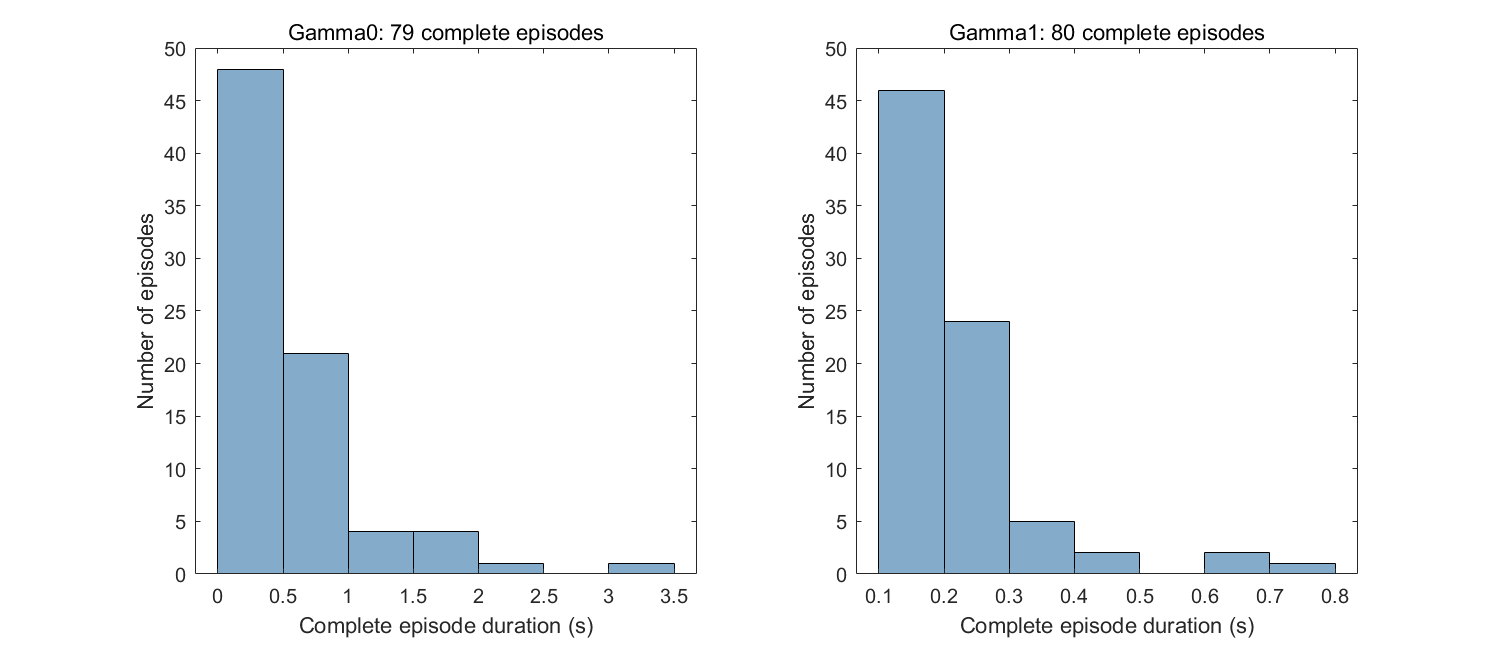

fig=figure('Color','w','Position',[100 100 1000 430]);
for stateValue=0:1
    subplot(1,2,stateValue+1);
    values=E.Duration_s(E.State==stateValue & E.Complete);
    if ~isempty(values),histogram(values,'FaceColor',[0.2 0.45 0.65]);end
    xlabel('Complete episode duration (s)'); ylabel('Number of episodes');
    title(sprintf('Gamma%d: %d complete episodes',stateValue,numel(values)));
end
exportgraphics(fig,fullfile(outDir,'state_duration_distributions.png'),'Resolution',180);

% When pooling multiple discontinuous segments, analyze each independently.
% Never permit an episode to cross a segment boundary.